**L1 - SVM with Soft Margin - Linear Kernel**

Objective Function is


$$\min_{w,\xi ,C} \;\frac{1}{2}w^T w+C\sum_{i=1}^m \xi_i$$


subject to


$$\begin{array}{l}
d_i \left(w^T x_i -\gamma \right)+\xi_i -1\ge 0,\;\;\;1\le i\le m\\
{\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\xi }_i \ge 0,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;1\le i\le m
\end{array}$$



$$\begin{array}{l}
w=\textrm{coefficient}\;\textrm{vector}\;\textrm{wrt}\;\textrm{hyper}\;\textrm{plane}\\
\gamma =\textrm{Intercept}\\
C=\textrm{Control}\;\textrm{Parameter}\;\left(\textrm{control}\;\textrm{weightage}\right)
\end{array}$$


clear 
close all

X=[1 0 0 2 2 2 3 -1;0 1 0 2.5 2 3 2 0]'; % training data or input data
d=[-1 -1 -1 -1 1 1 1 1]'; % target
e=ones(length(d),1);
C = 1;

cvx_begin quiet
variable w(2);
variable gama;
variable psii(8); % psii as a column vector
minimize (0.5*(w'*w)+C*sum(psii));
subject to
d.*(X*w-gama*e)>=1-psii;
psii>=0;
cvx_end

w1 = w(1)

w1 = 0.5000

w2 = w(2)

w2 = 0.5000

gama

gama = 1.5000

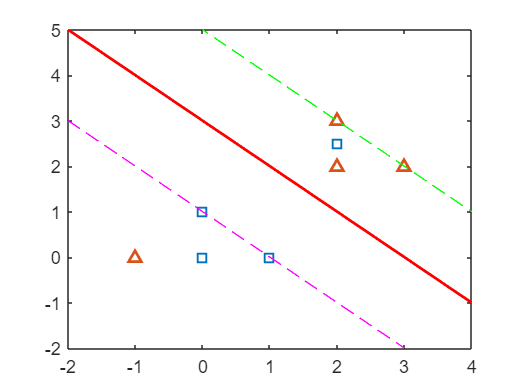



plot(X(1:4,1), X(1:4,2),'s', LineWidth=1.5);% plot-1 points
hold on

plot(X(5:8,1), X(5:8,2),'^', LineWidth=1.5);% plot+1 points
hold on

x1=-2:5;

x2=-(w(1)/w(2))*x1+(gama/w(2));
plot(x1,x2,LineWidth=1.5,Color='r'); % draw the classifier line
hold on

x2=-(w(1)/w(2))*x1+((-1+gama)/w(2));
plot(x1,x2,'m--') % draw the lower bounding line
hold on

x2=-(w(1)/w(2))*x1+((1+gama)/w(2));
plot(x1,x2, 'g--') % draw the upper bounding line
axis([-2 4 -2 5])

**L2 - Norm SVM with Soft Margin - Linear Kernel**

Objective function is


$$\min_{w,\xi ,C} \;\frac{1}{2}w^T w+0\ldotp 5*C\sum_{i=1}^m {\xi_i }^{\;2}$$


Subject to 


$$d_i \left(w^T x_i -\gamma \right)+\xi_i -1\ge 0,\;\;\;1\le i\le m$$



$${\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\xi }_i \ge 0,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;1\le i\le m$$


clear 
close all

X=[1 0 0 2 2 2 3 -1;0 1 0 2.5 2 3 2 0]';
d=[-1 -1 -1 -1 1 1 1 1]';
e=ones(length(d),1);
C = 1;

cvx_begin quiet
variable w(2);
variable gama;
variable psii(8); % psii as a column vector
minimize (0.5*(w'*w)+0.5*C*sum(psii)^2);
subject to
d.*(X*w-gama*e)>=1-psii;
psii>=0;
cvx_end

w1 = w(1)

w1 = 0.5000

w2 = w(2)

w2 = 0.5000

gama

gama = 1.5000


plot(X(1:4,1), X(1:4,2),'s', LineWidth=1.5);% plot-1 points
hold on

plot(X(5:8,1), X(5:8,2),'^', LineWidth=1.5);% plot+1 points
hold on

x1=-2:5;

x2=-(w(1)/w(2))*x1+(gama/w(2));
plot(x1,x2,LineWidth=1.5,Color='r'); % draw the classifier line
hold on

x2=-(w(1)/w(2))*x1+((-1+gama)/w(2));
plot(x1,x2,'m--') % draw the lower bounding line 
hold on

x2=-(w(1)/w(2))*x1+((1+gama)/w(2));
plot(x1,x2, 'g--') % draw the upper bounding line
axis([-2 4 -2 5])

**L1 Norm with and without Bias Term - Non Linear SVM**

objective function in Matrix form


$$\textrm{minimise}\;L_D \left(u\right)=\frac{1}{2}u^T Q\;u-e^T u$$


subject to


$$d^T u=0,\;\;\;\;\;\;\;\;\;\;0\le u\le C\;e$$



$$Q=K\ldotp *\left(d*d^T \right);\;\;\;\textrm{where}\;K\;\textrm{is}\;\textrm{kernel}\;\textrm{matrix}$$


clc
clear
close all

A=[1 2 5 6]';
d=[-1 -1 1 -1]';
e = ones(length(A),1);

k = (A*A' +1).^2;
Q = k.*(d*d');

C=50;

cvx_begin quiet
variable u(4)
minimize (0.5*u'*Q*u-e'*u)
% 4*1 * 4*4 * 1*4
subject to 
d'*u==0;
0<=u<=C*e;
cvx_end

u1 = round(u(1))

u1 = 0

u2 = u(2)

u2 = 2.5000

u3 = u(3)

u3 = 7.3333

u4 = u(4)

u4 = 4.8333


$$\begin{array}{l}
f\left(x\right)=\mathrm{sign}\left\lbrack \sum_{i=1}^4 d_i {\;u}_i \;{\left(x_i^T \;x+1\right)}^2 -\gamma \right\rbrack \\
\;\;\;\;\;\;\;\;\;\;=\mathrm{sign}\left\lbrack \left(-1\right)\left(2\ldotp 5\right){\left(2x+1\right)}^2 +\left(1\right)\left(7\ldotp 3333\right){\left(5x+1\right)}^2 +\left(-1\right)\left(4\ldotp 8333\right){\left(6x+1\right)}^2 -\gamma \right\rbrack \\
\;\;\;\;\;\;\;\;\;\;=\mathrm{sign}\left\lbrack -0\ldotp 666667x^2 +5\ldotp 333333x-\gamma \right\rbrack 
\end{array}$$


Bias $\gamma$ is determined from the requirement that at the SV points 2, 5, 6 the outputs must be -1, 1 and -1 respectively. Hence, $\gamma =9$ resulting in the decision function.

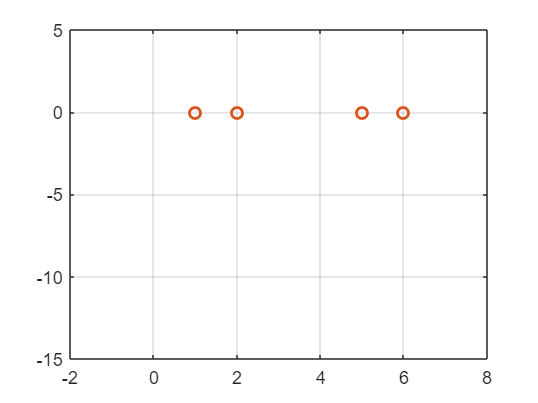

x = -1:0.01:8;
y = -0.67*x.^2+5.33*x-9;
plot(x,y)
hold on
plot(A,zeros(4,1),'o', LineWidth=1.5)
grid on

**L2 Norm with and without Bias Term - Non Linear SVM**

objective function in Matrix form


$$\min_u \;L_D \left(u\right)=\frac{1}{2}u^T \;D\left(K+\frac{1}{C}\right)D\;u-e^T u$$


(or)


$$\min_u \;L_D \left(u\right)=\frac{1}{2}u^T Q\;u-e^T u$$


subject to


$$d^T u=0,\;\;\;\;\;\;\;\;\;\;u\ge 0$$



$$Q=\left(K+\frac{1}{C}\right)\ldotp *\left(d*d^T \right);\;\;\;\textrm{where}\;K\;\textrm{is}\;\textrm{kernel}\;\textrm{matrix}$$


clc
clear
close all

A=[1 2 5 6]';    % 1-D point
d=[-1 -1 1 -1]';
e = ones(length(A),1);
k = (A*A' +1).^2; % kernel matrix
C=50; % weight
Q = (k + 1/C).*(d*d');

cvx_begin quiet
variable u(4)
minimize (0.5*u'*Q*u-e'*u)
% 4*1 * 4*4 * 1*4
subject to 
d'*u==0;
u>=0;
cvx_end

u1 = round(u(1));
u2 = u(2);
u3 = u(3);
u4 = u(4);


$$\begin{array}{l}
f\left(x\right)=\mathrm{sign}\left\lbrack \sum_{i=1}^4 d_i {\;u}_i \;{\left(x_i^T \;x+1\right)}^2 -\gamma \right\rbrack \\
\;\;\;\;\;\;\;\;\;\;=\mathrm{sign}\left\lbrack \left(-1\right)\left(2\ldotp 5\right){\left(2x+1\right)}^2 +\left(1\right)\left(7\ldotp 3333\right){\left(5x+1\right)}^2 +\left(-1\right)\left(4\ldotp 8333\right){\left(6x+1\right)}^2 -\gamma \right\rbrack \\
\;\;\;\;\;\;\;\;\;\;=\mathrm{sign}\left\lbrack -0\ldotp 666667x^2 +5\ldotp 333333x-\gamma \right\rbrack 
\end{array}$$


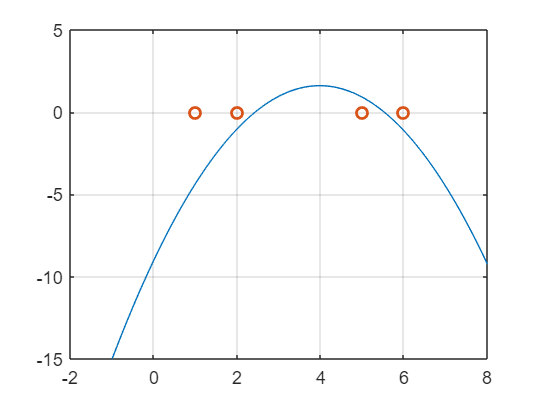

x = -1:0.01:8;
y = -0.67*x.^2+5.33*x-9;
plot(x,y)
hold on
plot(A,zeros(4,1),'o', LineWidth=1.5)
grid on